%% Biosignal Processing - Lab 3 Part 1
%% AR-model estimation

clear; close all; clc;

%% Task 0.0 - Load data

data = load('lms_test_data.mat');

x = data.x;
v1 = data.v1;

% True data
w_true = data.true_data.w_trajectory;
s_true = data.true_data.s;
v0_true = data.true_data.v0;

N = length(x);

%% Task 1.0 - Filter Implementation
% In file my_lms_artefact_canceller.m


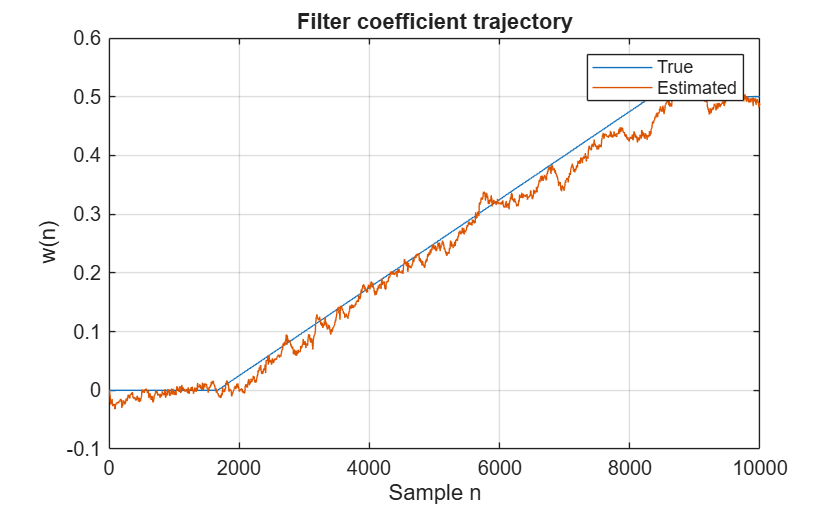

%% Task 2.0 - Filter testing

mu = 0.0001;
[s_hat, w, w_trajectory] = my_lms_artefact_canceller(x, v1, mu);

%% Task 2.1 - Filter coefficient trajectory

figure;
plot(w_true);
hold on;
plot(w_trajectory);

xlabel('Sample n');
ylabel('w(n)');
legend('True', 'Estimated');
title('Filter coefficient trajectory');
grid on;

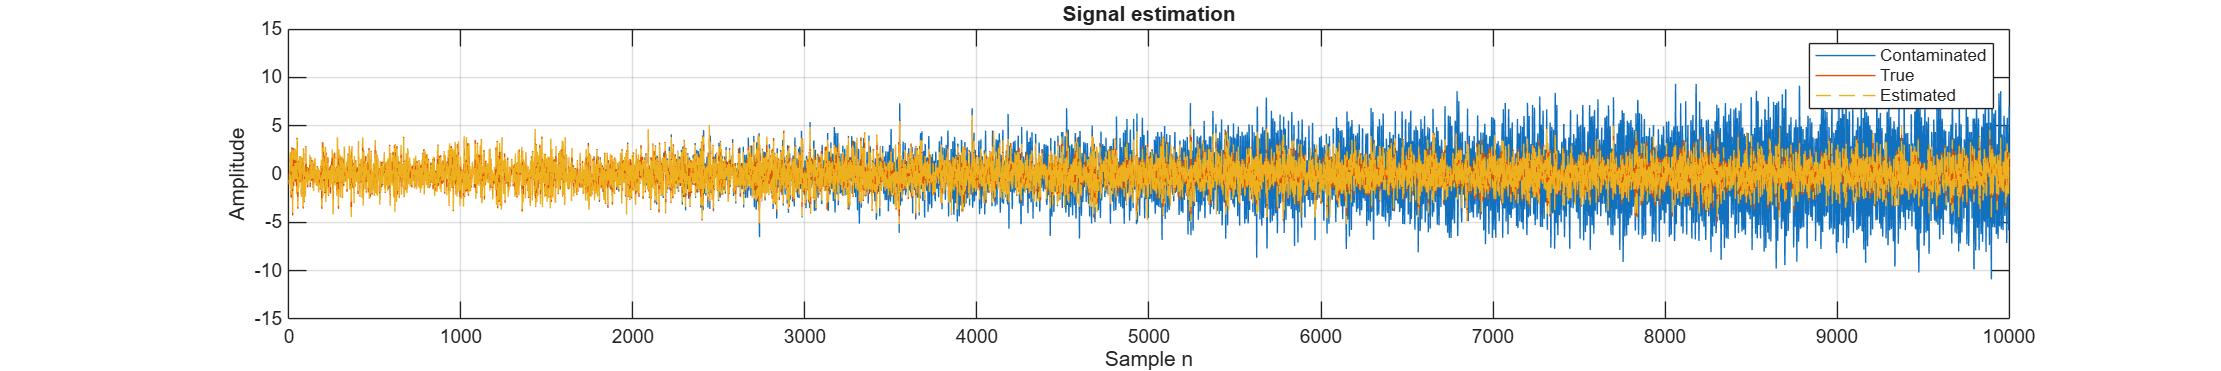

%% Task 2.2 - Signal estimation

figure('Position', [100 100 3000 500]);

plot(x);
hold on;
plot(s_true);
plot(s_hat, '--');

xlabel('Sample n');
ylabel('Amplitude');
legend('Contaminated', 'True', 'Estimated');
title('Signal estimation');
grid on;

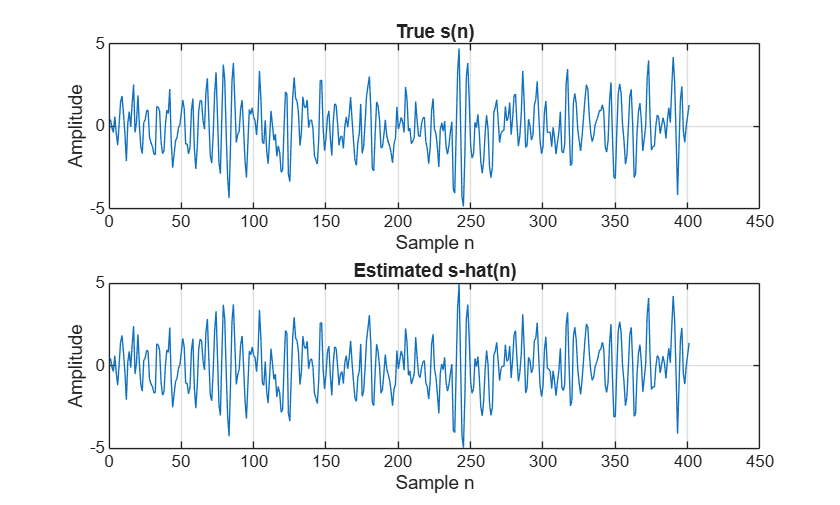

figure;

% True signal
subplot(2,1,1);
plot(s_true(5000:5400));
xlabel('Sample n');
ylabel('Amplitude');
title('True s(n)');
grid on;

% Estimated signal
subplot(2,1,2);
plot(s_hat(5000:5400));
xlabel('Sample n');
ylabel('Amplitude');
title('Estimated s-hat(n)');
grid on;

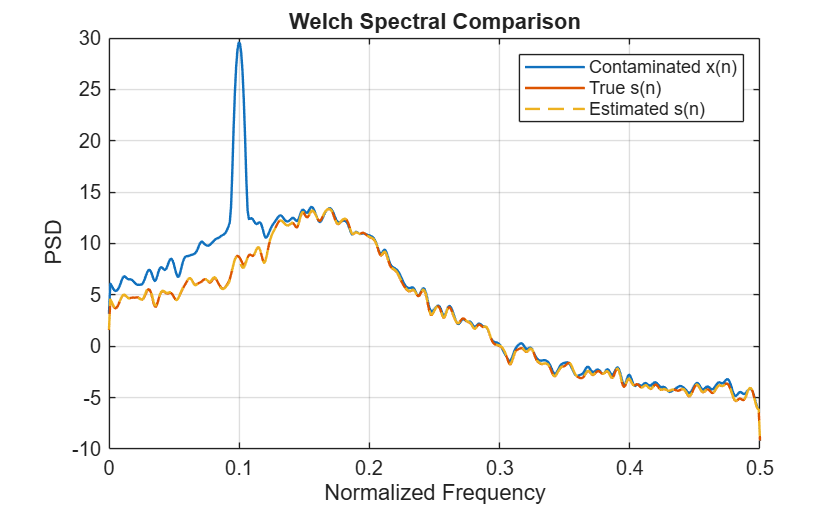

%% Task 2.3 - Spectral comparison

% Welch parameters
window_length = 256;
overlap = round(0.5 * window_length);
nfft = 1024;

% Estimate power spectral densities
[psd_x, f] = pwelch(x, window_length, overlap, nfft, 1);
[psd_s, ~] = pwelch(s_true, window_length, overlap, nfft, 1);
[psd_shat, ~] = pwelch(s_hat, window_length, overlap, nfft, 1);

% Plot spectra
figure;

plot(f, 10*log10(psd_x), 'LineWidth', 1.2);
hold on;
plot(f, 10*log10(psd_s), 'LineWidth', 1.2);
plot(f, 10*log10(psd_shat), '--', 'LineWidth', 1.2);

xlabel('Normalized Frequency');
ylabel('PSD');
title(['Welch Spectral Comparison']);
legend('Contaminated x(n)', 'True s(n)', 'Estimated s(n)');
grid on;

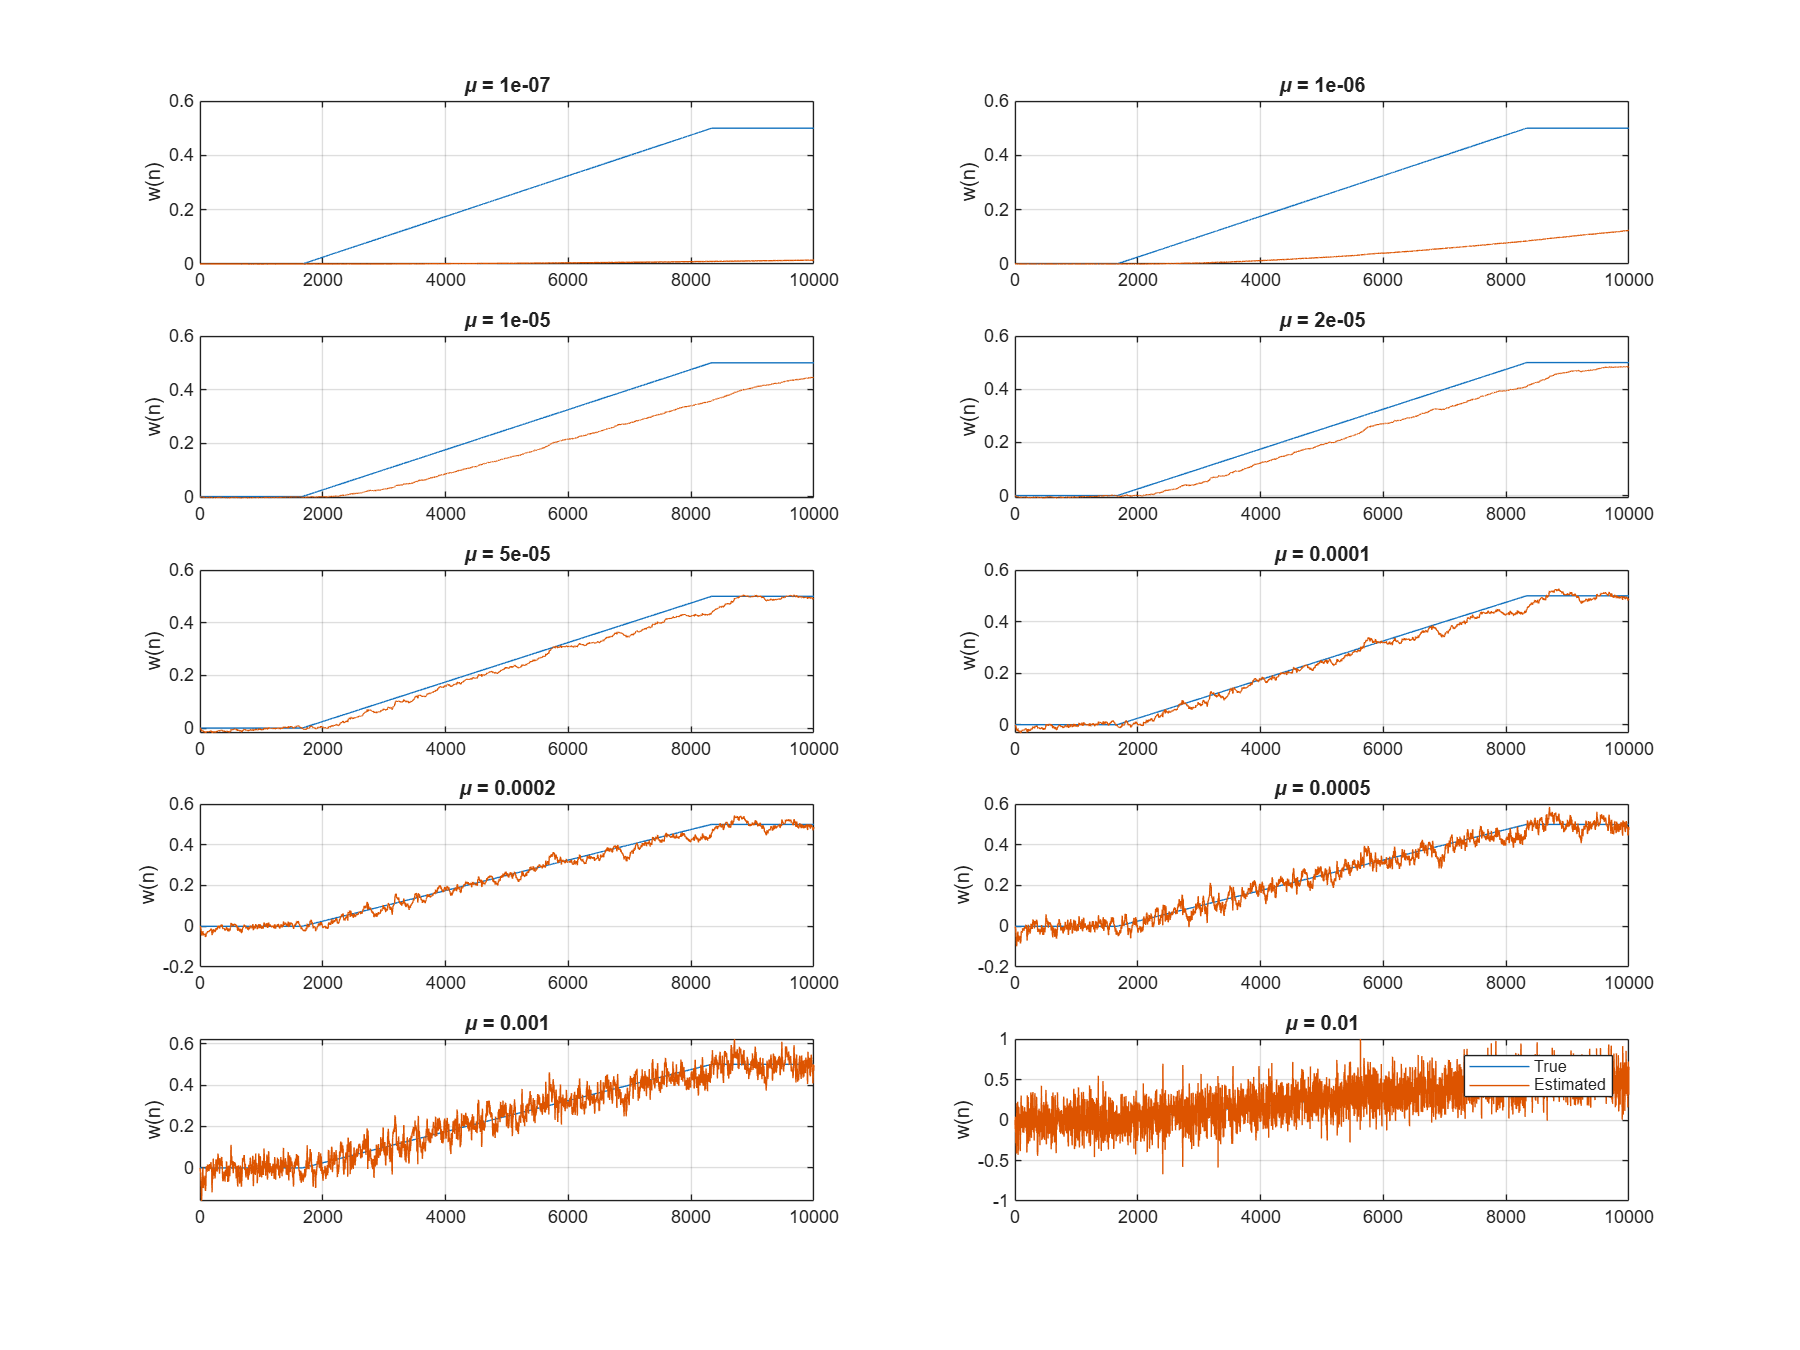

%% Task 2.4 - Effect of step size

mu_values = [0.0000001, 0.000001, 0.00001, 0.00002, 0.00005, 0.0001, 0.0002, 0.0005, 0.001, 0.01];
num_mu = length(mu_values);

s_hat_all = zeros(length(x), num_mu);
w_trajectory_all = zeros(length(x), num_mu);

for i = 1:num_mu
    [s_hat_all(:,i), ~, w_trajectory_all(:,i)] = my_lms_artefact_canceller(x, v1, mu_values(i));
end

% Compare filter coefficient trajectories

figure('Position', [100 100 1200 900]);

tiledlayout(5,2);

for i = 1:num_mu

    nexttile;

    plot(w_true);
    hold on;
    plot(w_trajectory_all(:,i));

    ylabel('w(n)');
    title(['\mu = ', num2str(mu_values(i))]);
    grid on;

end

legend('True', 'Estimated');

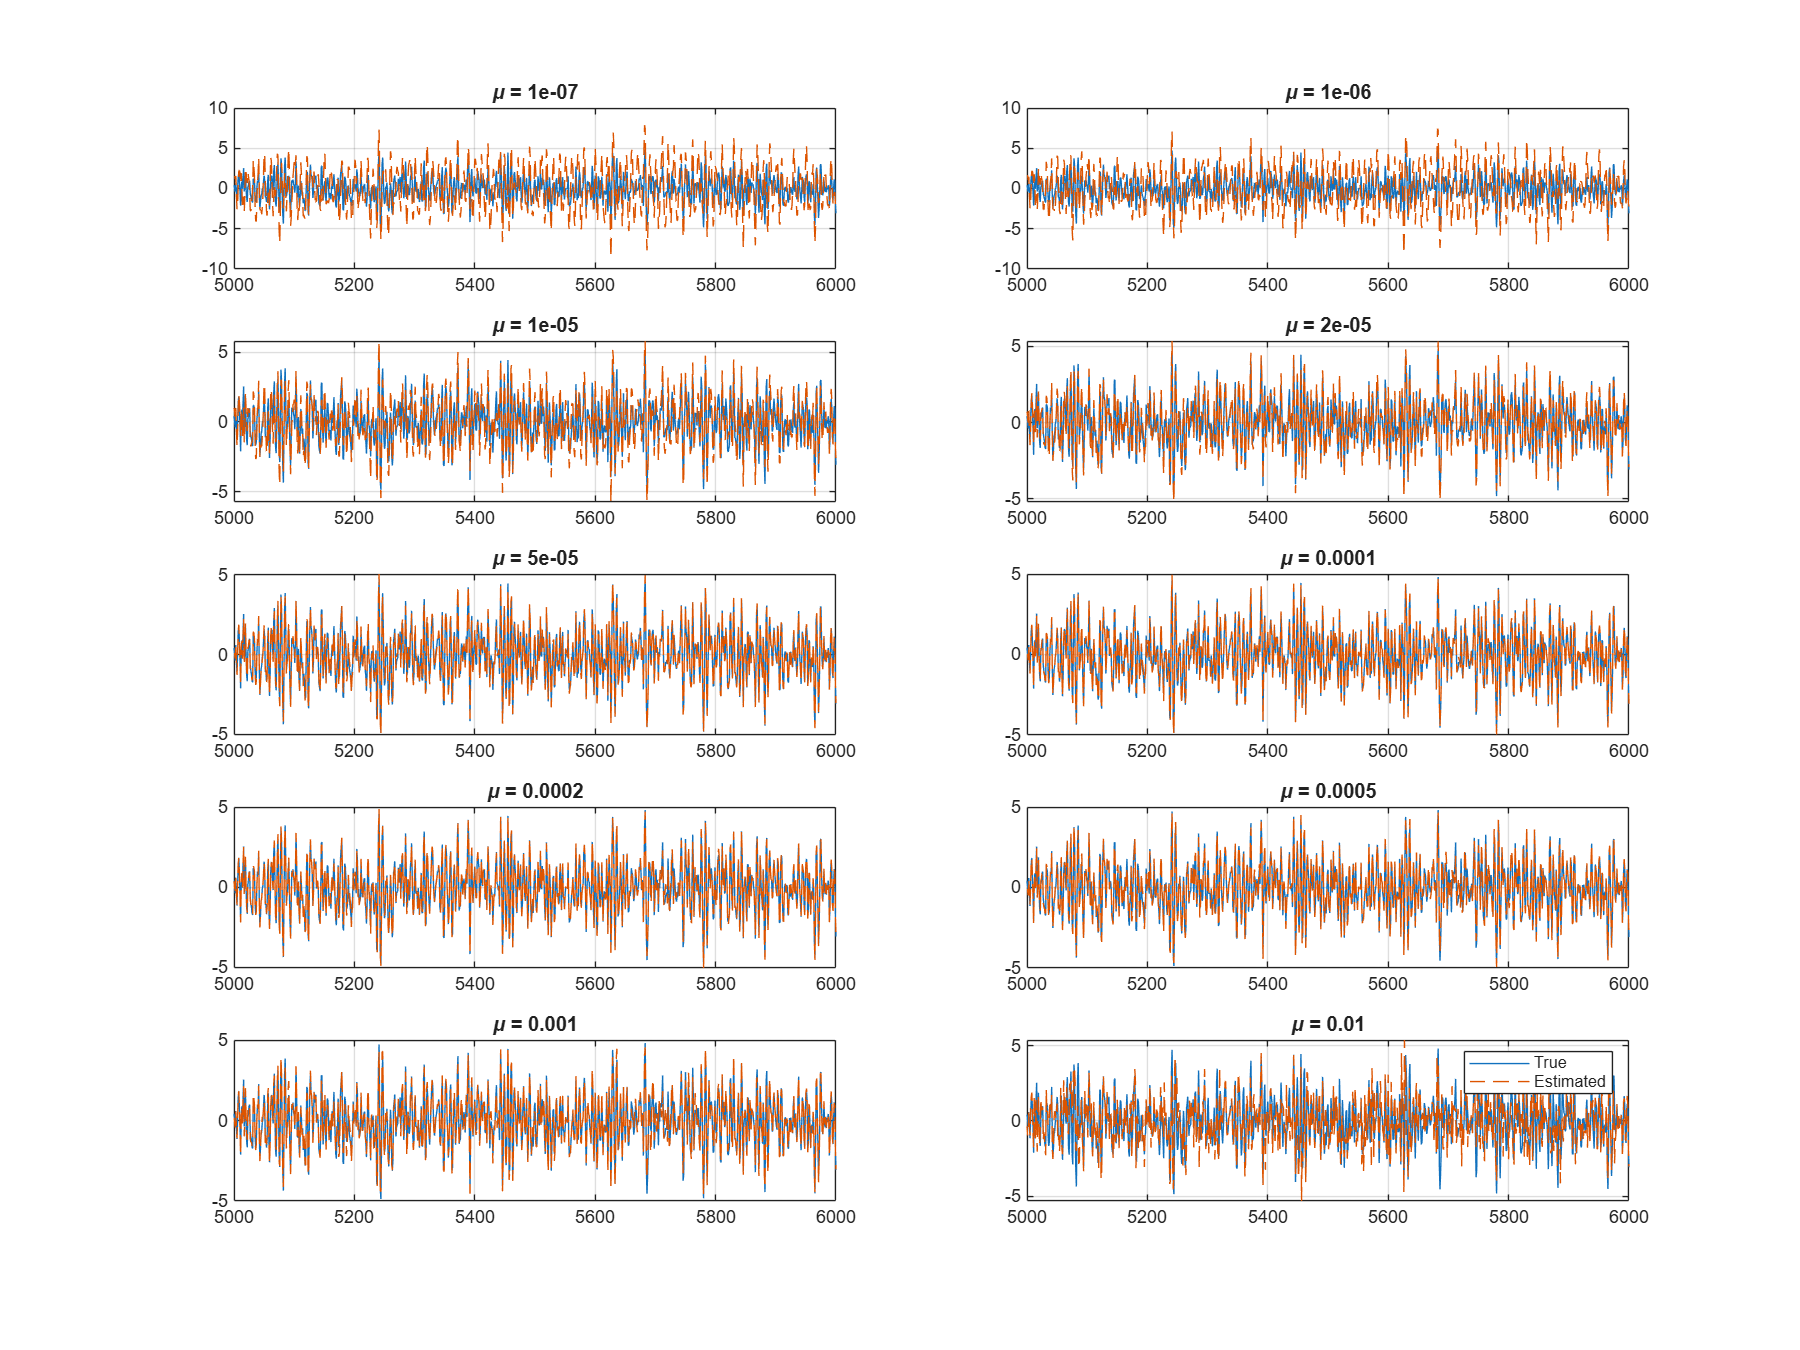


% Compare estimated signals

figure('Position', [100 100 1200 900]);

for i = 1:num_mu

    subplot(5,2,i);

    plot(s_true);
    hold on;
    plot(s_hat_all(:,i), '--');
    
    % Only first 500 samples
    xlim([5000 6000]);

    title(['\mu = ', num2str(mu_values(i))]);
    grid on;

end

legend('True', 'Estimated');

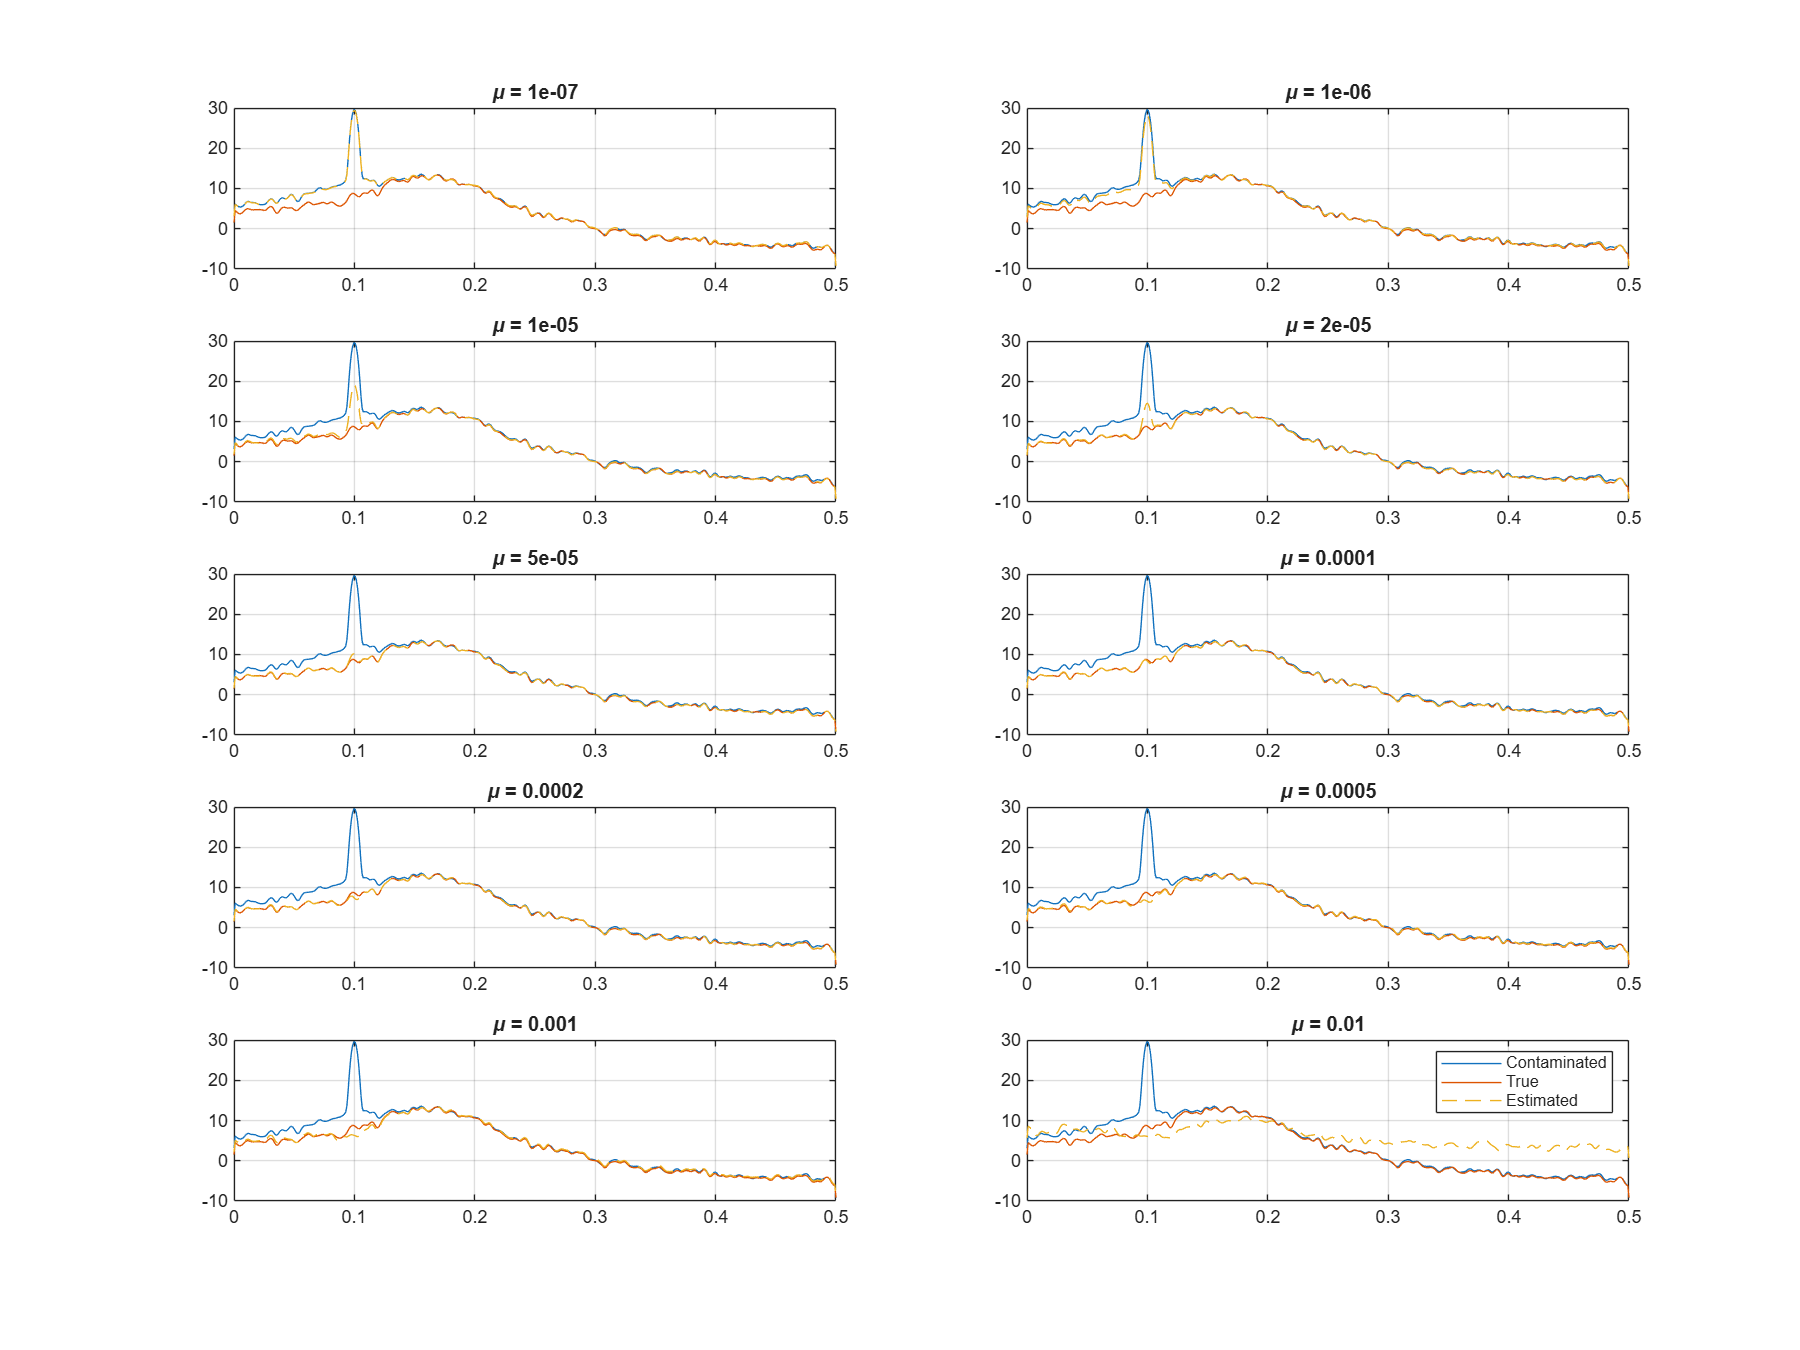


% Compare spectra

%% Calculate spectra for different mu

for i = 1:num_mu
    [psd_shat_all(:,i), f_all(:,i)] = pwelch(s_hat_all(:,i), window_length, overlap, nfft, 1);
end


%% Plot spectra

figure('Position', [100 100 1200 900]);

for i = 1:num_mu

    subplot(5,2,i);

    plot(f, 10*log10(psd_x));
    hold on;
    plot(f, 10*log10(psd_s));
    plot(f_all(:,i), 10*log10(psd_shat_all(:,i)), '--');

    title(['\mu = ', num2str(mu_values(i))]);
    grid on;

end

legend('Contaminated', 'True', 'Estimated');